clear all;
fname = 'step1';
file = load('step1.mat');
% Hard-define the plotting lim based on my Google Maps screenshot
xl = [-8,84];
yl = [36,-54];
img = imread("map.png");

xl = [-7,30];
yl = [25,-17];

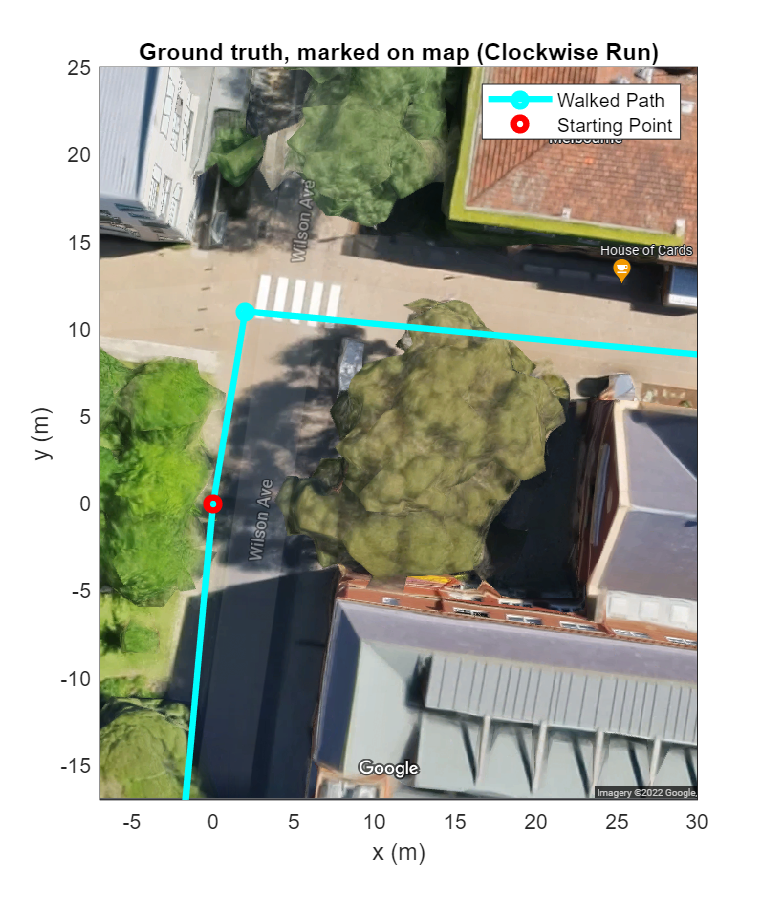

% Ground truth plotting
fig=gcf;
fig.Position(4)=653;

% Google map scaling ratio is used as frame of reference 
% to estimate checkpoint coordinates
ct = [0,0;
      2,11;
      70,5;
      66,-10;
      75,-12;
      70,-42;
      10,-36;
      -2,-20;
      0,0];
plot(ct(:,1),ct(:,2),'c-o',LineWidth=3)
title('Ground truth, marked on map (Clockwise Run)');
xlabel('x (m)');
ylabel('y (m)');

% Add map for reference
hold on;
uistack(image(xl,yl,img),'bottom');
plot([0],[0],'ro',LineWidth=3);
legend('Walked Path','Starting Point',Location='northeast')
xlim(xl);
ylim([yl(2),yl(1)]);
hold off;

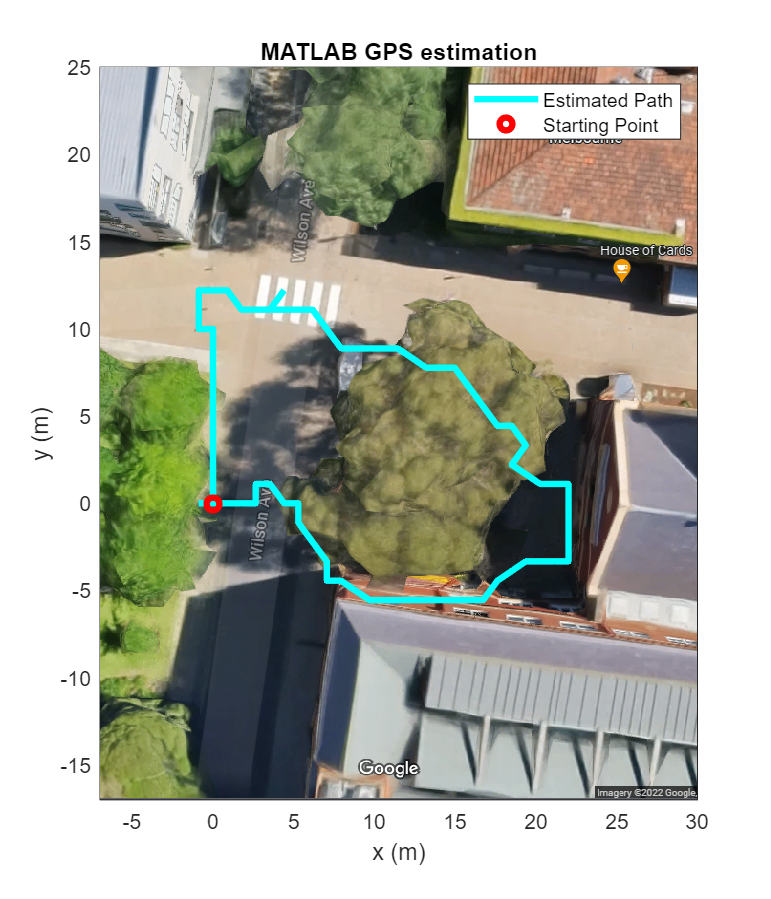

% GPS plotting
p = file.Position;
loc = [0,0,0];
cps = zeros(size(p,1),3);
for i=1:size(p,1)-1
    % Conversion of lat-long to meter displacement
    r = lla2enu([p.latitude(i+1),p.longitude(i+1),0], ...
        [p.latitude(i),p.longitude(i),0],'flat');
    loc = loc + r;
    cps(i+1,:) = loc;
end
plot(cps(:,1),cps(:,2),'c-',LineWidth=3)
title('MATLAB GPS estimation');
xlabel('x (m)');
ylabel('y (m)');

% Add map for reference
hold on;
uistack(image(xl,yl,img),'bottom');
plot([0],[0],'ro',LineWidth=3);
legend('Estimated Path','Starting Point',Location='northeast')
xlim(xl);
ylim([yl(2),yl(1)]);
hold off;

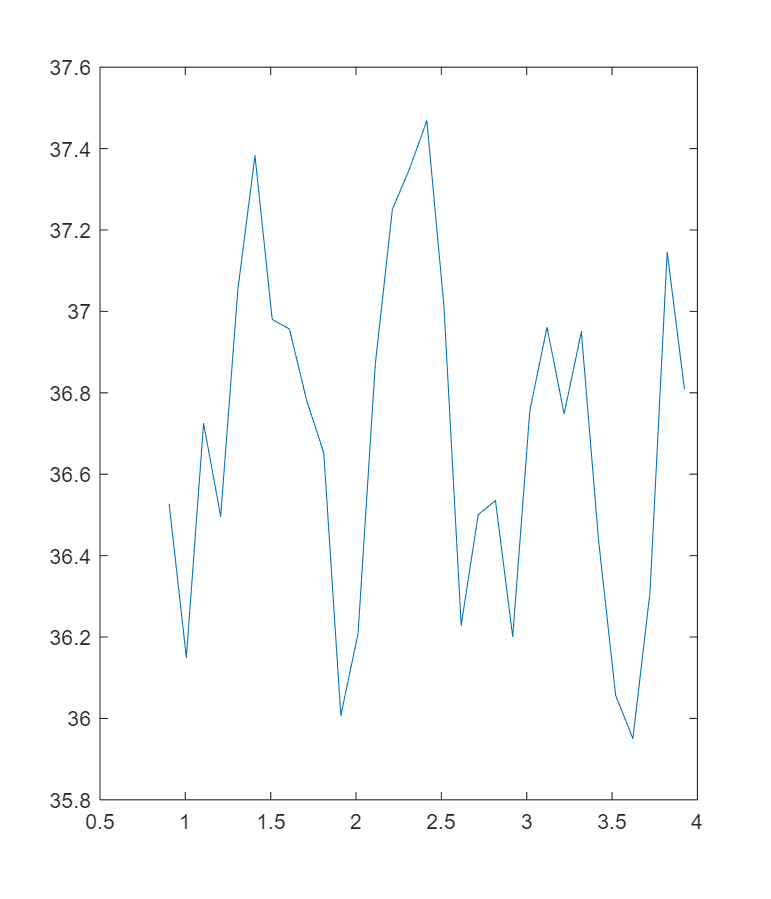

calibration_time = [1,4];
m = file.MagneticField;
tm = get_t(m);
% Sampling frequency
fm=1/(tm(2)-tm(1));

% Calibration
calib_idx_start = round(calibration_time(1) * fm);
calib_idx_end = round(calibration_time(2) * fm);
tc = tm(calib_idx_start:calib_idx_end);
xc = m.X(calib_idx_start:calib_idx_end);
yc = m.Y(calib_idx_start:calib_idx_end);
zc = m.Z(calib_idx_start:calib_idx_end);

cm = rad2deg(atan2(yc,xc));
plot(tc,cm);

[mu_m, sig_m] = normal_dist(cm,ones(calib_idx_end-calib_idx_start+1,1))

mu_m = 36.6925

sig_m = 0.4161

%mf_est = unwrap(dm,thresh);

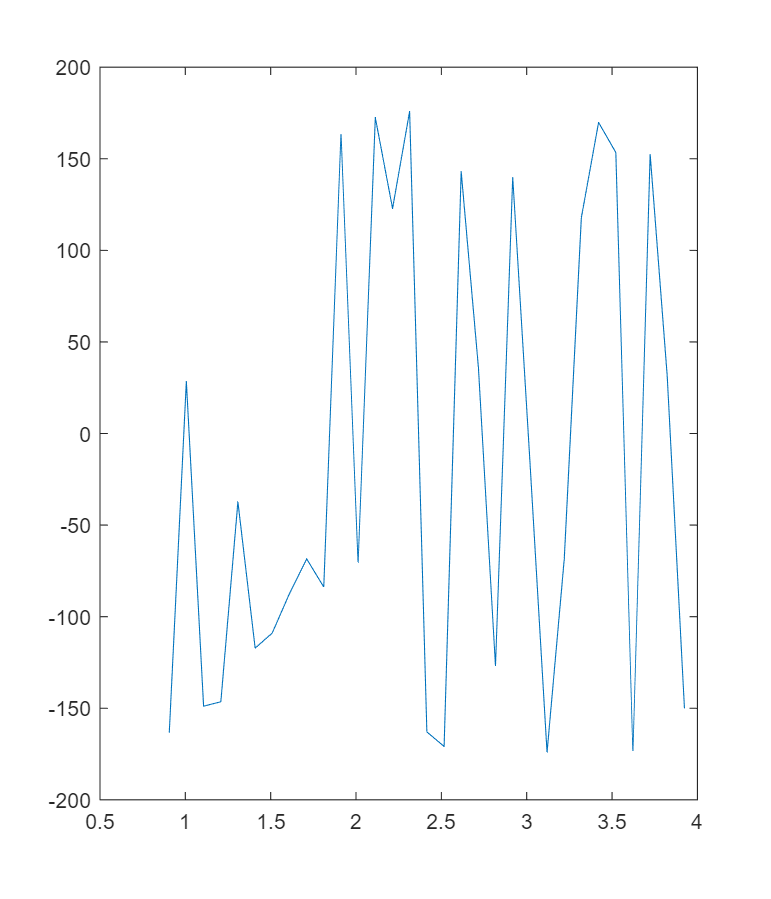

g = file.AngularVelocity;
tg = get_t(g);
% Sampling frequency
fg=1/(tg(2)-tg(1));

% Calibration
calib_idx_start = round(calibration_time(1) * fm);
calib_idx_end = round(calibration_time(2) * fm);
tc = tg(calib_idx_start:calib_idx_end);
xc = g.X(calib_idx_start:calib_idx_end);
yc = g.Y(calib_idx_start:calib_idx_end);
zc = g.Z(calib_idx_start:calib_idx_end);

cg = rad2deg(atan2(yc,xc));
plot(tc,cg);

[mu_g, sig_g] = normal_dist(cg,ones(calib_idx_end-calib_idx_start+1,1))

mu_g = -15.0569

sig_g = 128.1842

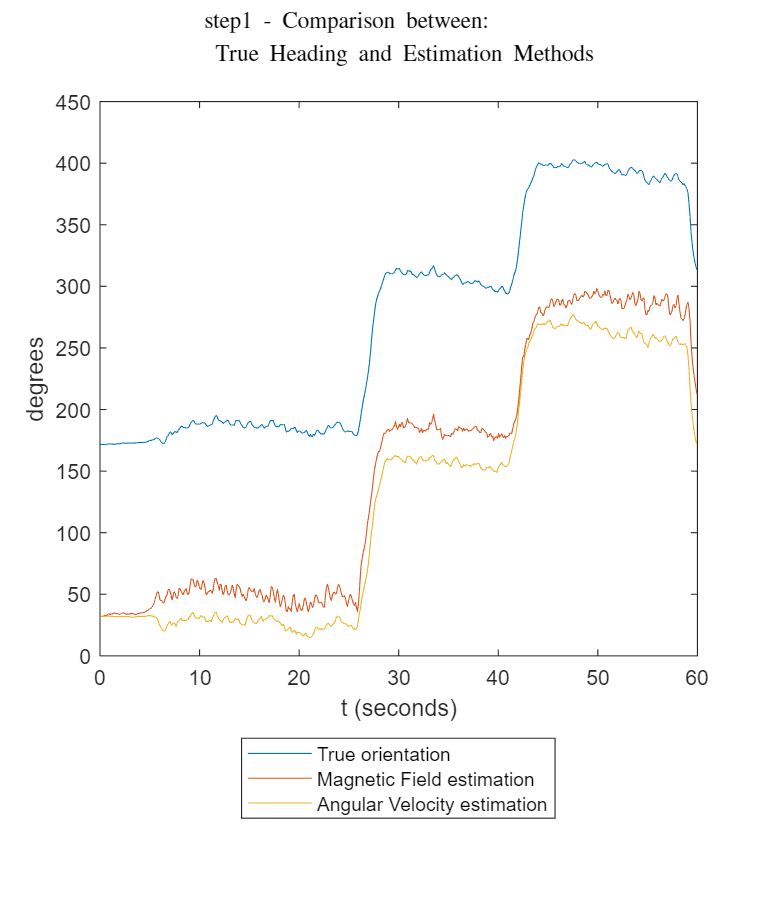

[dt,dm,da] = heading(fname);

T = 1/fg;
phi = [1  T  -1;
       0  1  0;
       0  0  1];
H = [1 0 0];

varg = sig_g^2;
Q = [varg*T^2 varg*T 0;
     varg*T   varg   0;
     0        0      0];
%Q = eye(3);
% R = [0 0 0;
%     0 0 0;
%     0 0 sig_m^2];
R = sig_m^2;

xe0 = [dm(calib_idx_start),0,0]';
P00 = Q;%[0,0,0;0,0,0;0,0,0];
dx0 = [0,0,0]';

y = zeros(length(da),3);
y(:,1) = dm;
y(:,2) = g.Z;
y(:,3) = dm-da;

[kest,kpred,kco] = kf(y,phi,H,Q,R,xe0,P00,dx0)

kest =    34.3545 -153.3654         0
   29.8380  -77.5277         0
   30.6346  -14.0467         0
   31.7070    4.7345         0
   32.5699   12.5476         0
   32.7941    9.2483         0
   33.0465   10.6093         0
   33.6746   18.8040         0
   33.9491   19.2378         0
   33.7549   14.3290         0


kpred =    60.1710         0         0
   18.9935 -153.3654         0
   21.7573  -77.5277         0
   29.0685  -14.0467         0
   31.4717    4.7345         0
   33.2577   12.5476         0
   32.8553    9.2483         0
   32.5229   10.6093         0
   33.8881   18.8040         0
   34.4447   19.2378         0


kco =     0.9169    0.8332    0.8366    0.8368    0.8364    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363    0.8363
    5.4469    5.8267    5.9822    5.9563    5.9502    5.9506    5.9507    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506    5.9506   

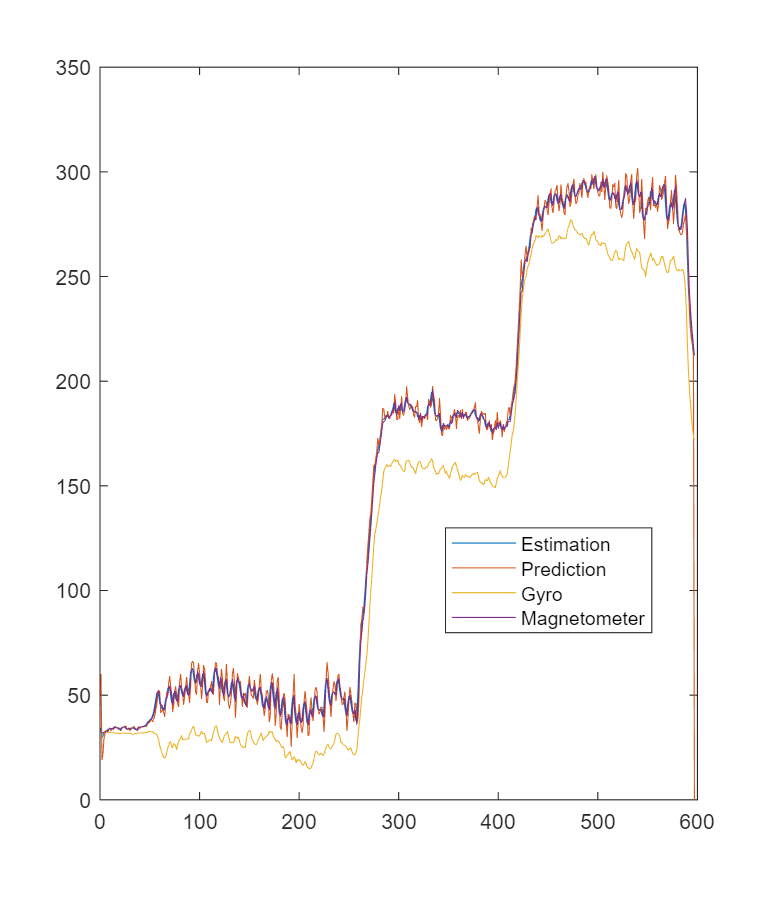

plot([kest(:,1),kpred(:,1),da,dm])
legend('Estimation','Prediction','Gyro','Magnetometer',Location='best')

T = 1/fg;
phi = [1  T;
       0  1];
H = [1 0];

varg = sig_g^2;
Q = [sig_m^2   0;
     0      sig_g^2];
%Q = eye(3);
% R = [0 0 0;
%     0 0 0;
%     0 0 sig_m^2];
R = sig_m^2;

xe0 = [dm(calib_idx_start),0]';
P00 = Q;%[0,0,0;0,0,0;0,0,0];
dx0 = [0,0]';

y = zeros(length(da),2);
y(:,1) = dm;
y(:,2) = g.Z;

[kest,kpred,kco] = kf(y,phi,H,Q,R,xe0,P00,dx0)

kest =    32.0165  -19.2128
   32.0070   -0.1526
   32.3686    3.5684
   32.2222   -1.4342
   32.7841    5.5414
   32.7040   -0.7735
   33.0835    3.7439
   33.8995    8.0663
   33.9618    0.6393
   33.6203   -3.3693


kpred =    33.9610         0
   30.0760  -19.2128
   31.9916   -0.1526
   32.7290    3.5684
   32.0773   -1.4342
   33.3437    5.5414
   32.6258   -0.7735
   33.4616    3.7439
   34.7142    8.0663
   34.0264    0.6393


kco =     0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990    0.9990
    9.8704    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605    9.8605   

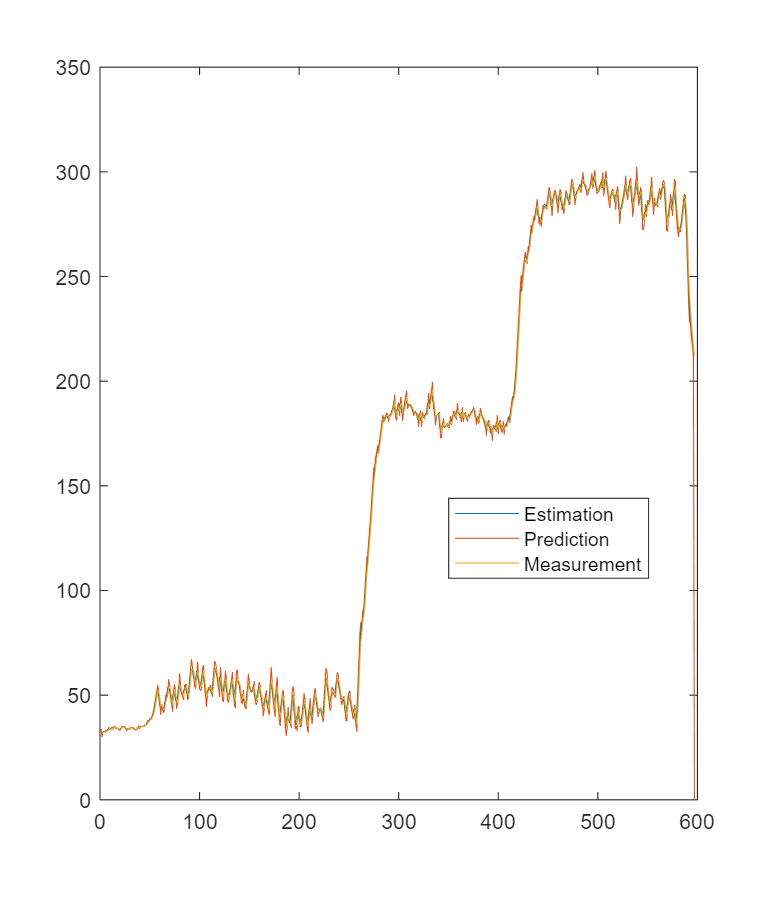

plot([kest(:,1),kpred(:,1),dm])
legend('Estimation','Prediction','Measurement',Location='best')

% Re-map coordinate to match world coordinates
r = roty(180)*rotz(105);
% Hard-defined step length by measurement
sl = 0.085;

or = kest%lowpass(kest,0.05,20);

or =    32.0149  -11.5610         0
   32.0080   -0.0841         0
   32.3686    3.5627         0
   32.2222   -1.4394         0
   32.7841    5.5485         0
   32.7040   -0.7799         0
   33.0835    3.7485         0
   33.8995    8.0707         0
   33.9618    0.6317         0
   33.6203   -3.3735         0


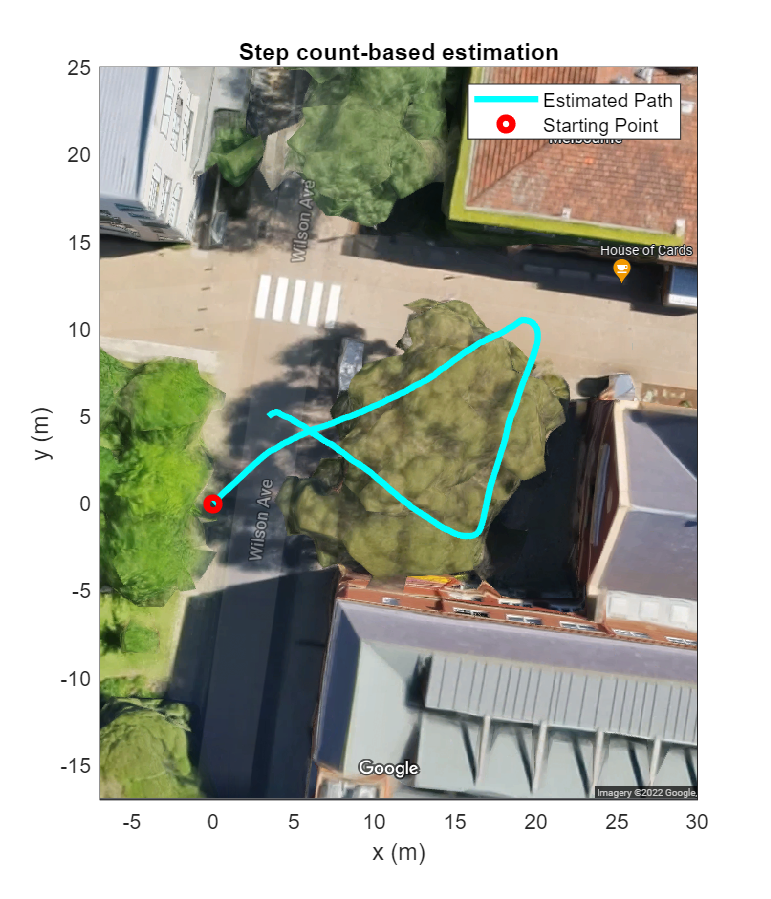

%plot(or)

len = length(or);
coord = zeros(len,2);
coord(1,:) = [0,0];

for i = 1:len-1
    incr = sl*r*[cos(deg2rad(or(i)));sin(deg2rad(or(i)));0];
    coord(i+1,:) = coord(i,:) + incr([1,2])';
end

plot(coord(:,1),coord(:,2),'c-',LineWidth=3)
title('Step count-based estimation');
xlabel('x (m)');
ylabel('y (m)');

% Add map for reference
hold on;
uistack(image(xl,yl,imread("map.png")),'bottom');
plot([0],[0],'ro',LineWidth=3);
legend('Estimated Path','Starting Point',Location='northeast')
xlim(xl);
ylim([yl(2),yl(1)]);
hold off;

% f = 20;
% T = 1/f;
% phi = [1  T  0;
%        0  1  T;
%        0  0  1];
% H = [1 0 0];
% 
% Q = eye(3)*0.05;
% R = 0.5;
% 
% xe0 = [0 0 0]';
% P00 = eye(3);
% dx0 = [0 0 0]';
% 
% x=linspace(-10,10,30);
% y = (x.^2 + 10*x +2) + randn(1,30);
% 
% [kest,kpred] = kf(y,phi,H,Q,R,xe0,P00,dx0);
% plot([kest(:,1),kpred(:,1),y'])

function [est,pred,K] = kf(y,phi,H,Q,R,xe0,P00,dx0)
    l = length(y);
    sz = length(xe0);
    xek1k1 = xe0;
    est = zeros(l,sz);
    pred = zeros(l,sz);

    dx = dx0;

    Pkk = P00;

    K = zeros(sz,l+1);
    K(:,1) = zeros(1,sz);
    for k=1:l-1
        xekk = xek1k1;
        xek1k = phi*xekk - [y(k+1,3);0;0];
        Pk1k = phi*Pkk*phi' + Q;

        %size(Pk1k*H' / (H*Pk1k*H'+R))
        K(:,k+1) = Pk1k*H' / (H*Pk1k*H'+R);
        xek1k1 = xek1k + K(:,k+1)*(y(k+1)-H*xek1k);
        I = eye(length(H));
        k_1 = I-K(:,k+1)*H;
        Pkk = k_1*Pk1k*k_1' + K(:,k+1)*R*K(:,k+1)';
        %dx(3) = dx(3) + xek1k1;
        
        pred(k,:) = xek1k;
        est(k,:) = xek1k1;
    end
    K = K(:,2:end);
end

function [truth,mf_est,av_est] = heading(filename)
    data = load(filename+".mat");
    m = data.MagneticField;
    a = data.AngularVelocity;
    o = data.Orientation;
    % a_data = [a.X, a.Y, a.Z];
    m_data = [m.X, m.Y, m.Z];
    % o_data = [o.X, o.Y, o.Z];
    
    ta = get_t(a);
    tm = get_t(m);
    to = get_t(o);
    % Sampling frequency
    f=1/(ta(2)-ta(1));
    
    % Discontinuity threshold in degrees to unwrap
    thresh = 300;
    
    % True orientation. Phone is facing up, so only X changes
    truth = unwrap(o.X,thresh);
    
    % Magnetometer calibration
    [A,b,~]  = magcal(m_data);
    M = (m_data-b)*A;
    
    % Heading estimation using magnetic field (Only atan2(y,x) changes)
    dm = rad2deg(atan2(M(:,2),M(:,1)));
    mf_est = unwrap(dm,thresh);
    % Remove constant to match with orientation
    %mf_est = mf_est - mf_est(1) + truth(1);
    
    % Heading estimation using angular velocity (Only Z changes)
    da = rad2deg(cumsum(-a.Z/f));
    av_est = da+mf_est(1);
    
    % Comparison plot
    plot(to,truth);
    hold on;
    plot(tm,mf_est);
    plot(ta,av_est);
    legend('True orientation','Magnetic Field estimation','Angular Velocity estimation','location','southoutside');
    title(append(filename,' - Comparison between:\newline True Heading and Estimation Methods\newline'));
    xlabel('t (seconds)');
    ylabel('degrees');
    print(append(filename,'_estimation_comparison.png'),'-dpng');
    hold off;
end

function t = get_t(a)
    out = [0;seconds(diff(a.Timestamp))];
    t = cumsum(out);
    %t = a.Timestamp.Second - a.Timestamp.Second(1)
    %t(t<0) = t(t<0) + 60;
end

function a_filtered = noise_filter(a_norm,f,sd_min,sd_max)
    a_tf = fft(a_norm - 9.8);
    a_tf = fftshift(a_tf);
    L = length(a_norm);
    freqs = f/L * linspace(0,L-1,L) - f/2;%plot(freqs,a_tf);
    
    [pks,loc] = findpeaks(abs(a_tf), freqs);
    l = ceil(length(loc)/2);
    [mu,sig] = normal_dist(loc(l:end),pks(l:end));
    
    % Set up filter
    fmin = mu + sd_min*sig;
    fmax = mu + sd_max*sig;
    % Filter
    a_filtered = bandpass(a_norm,[fmin,fmax],f);
end

function f = filter_1(a_norm,f,sd_min,sd_max)
    f = noise_filter(a_norm,f,sd_min,sd_max);
end

function f = filter_3(a,f)
    a_norm = ((a.X).^2 + (a.Y).^2 + (a.Z).^2).^0.5;
    f = noise_filter(a_norm,f);
end

function [t,a_norm] = get_a(file)
    a = file.Acceleration;
    calibration_time = 3;
    
    % Is the phone position stationary?
    stationary = true;
    
    % In case phone position is stationary, set up the gravity
    gravity_x = 0;
    gravity_y = 0;
    gravity_z = 9.8;
    gravity = sqrt(gravity_x^2 + gravity_y^2 + gravity_z^2);
    
    t = get_t(a);
    % Sampling frequency
    f=1/(t(2)-t(1));
    
    % Calibration
    calib_idx = round(calibration_time * f);
    tc = t(1:calib_idx);
    xc = a.X(1:calib_idx);
    yc = a.Y(1:calib_idx);
    zc = a.Z(1:calib_idx);
    
    if stationary
        % Use linear regression to get the bias values
        T = [ones(length(tc),1) tc];
        line_x = T\xc;
        X0 = line_x(1) - gravity_x;
        line_y = T\yc;
        Y0 = line_y(1) - gravity_y;
        line_z = T\zc;
        Z0 = line_z(1) - gravity_z;
    else
        [X0, Y0, Z0] = deal(0,0,0);
    end
    % Norm by time
    a_norm = ((a.X-X0).^2 + (a.Y-Y0).^2 + (a.Z-Z0).^2).^0.5;
end

function dv = int_est(a_norm,t)
    da = cumtrapz(t,a_norm-9.8);
    dv = cumtrapz(t,da);
end

function [mu,sig] = normal_dist(x,p)
    sum_x = 0;
    sum_var = 0;

    sum_p = sum(p);
    for i=1:length(x)
        sum_x = sum_x + x(i)*p(i)/sum_p;
    end
    mu = sum_x;
    for i=1:length(x)
        sum_var = sum_var + (x(i)-mu)^2;
    end
    sig = sqrt(sum_var/sum_p);
end

function l = step_count(file,s_length)%,truth)
    a = file.Acceleration;
    calibration_time = 3;
    
    % Is the phone position stationary?
    stationary = true;
    
    % In case phone position is stationary, set up the gravity
    gravity_x = 0;
    gravity_y = 0;
    gravity_z = 9.8;
    gravity = sqrt(gravity_x^2 + gravity_y^2 + gravity_z^2);
    
    t = a.Timestamp.Second - a.Timestamp.Second(1);
    t(t<0) = t(t<0) + 60;
    % Sampling frequency
    f=1/(t(2)-t(1));
    
    % Calibration
    calib_idx = round(calibration_time * f);
    tc = t(1:calib_idx);
    xc = a.X(1:calib_idx);
    yc = a.Y(1:calib_idx);
    zc = a.Z(1:calib_idx);
    
    if stationary
        % Use linear regression to get the bias values
        T = [ones(length(tc),1) tc];
        line_x = T\xc;
        X0 = line_x(1) - gravity_x;
        line_y = T\yc;
        Y0 = line_y(1) - gravity_y;
        line_z = T\zc;
        Z0 = line_z(1) - gravity_z;
    else
        [X0, Y0, Z0] = deal(0,0,0);
    end
    % Norm by time
    a_norm = ((a.X-X0).^2 + (a.Y-Y0).^2 + (a.Z-Z0).^2).^0.5;

    a_tf = fft(a_norm - gravity);
    a_tf = fftshift(a_tf);
    L = length(a_norm);
    freqs = f/L * linspace(0,L-1,L) - f/2;
    
    [pks,loc] = findpeaks(abs(a_tf), freqs);
    l = ceil(length(loc)/2);
    [mu,sig] = normal_dist(loc(l:end),pks(l:end));
    
    % Set up filter
    fmin = mu - 3*sig;
    fmax = mu + 3.5*sig;
    % Filter
    a_filtered = bandpass(a_norm,[fmin,fmax],f);
    
    % Use calibration segment to identify max prominence noise
    [~,~,~,pc] = findpeaks(a_filtered(1:calib_idx), freqs(1:calib_idx), 'SortStr','descend');
    
    % Ensure margin is large enough to prevent noise peaks
    b_norm = (X0^2+Y0^2+Z0^2)^0.5;
    if b_norm > 0.2 margin=b_norm; else margin=0.2; end 
    
    minP = pc(1) + margin; % Add bias norm as safe margin
    
    % Get the highest likely step frequency in the data
    maxStepFreq = mu + 4*sig;
    
    % Set up peak-finding parameters
    settings = struct('MinPeakDistance', 1/maxStepFreq, ...
                      'MinPeakProminence', minP);
    
    % Find peaks that correspond to steps
    [ps,lps] = findpeaks(a_filtered,t,settings);
    l = length(ps);

    dist = cumsum(ones(1,length(lps))) * s_length;
%     plot(lps,dist,'-',lps,dist,'o',lps,truth*ones(length(lps)),'--');
%     legend('Distance','Step detected','Actual distance','Location','best');
%     title('Distance by time using step count estimation');
%     xlabel('Time (seconds)');
%     ylabel('Distance (m)');
end

function r = roty(t)
    dt = deg2rad(t);
    r = [cos(dt) 0 sin(dt);
        0        1       0;
        -sin(dt) 0 cos(dt)];
end
function r = rotz(t)
    dt = deg2rad(t);
    r = [cos(dt) -sin(dt) 0;
        sin(dt)   cos(dt) 0;
        0         0       1];
end